clear, clc, close all
datetime('now')

ans = datetime
   31-May-2023 18:04:45


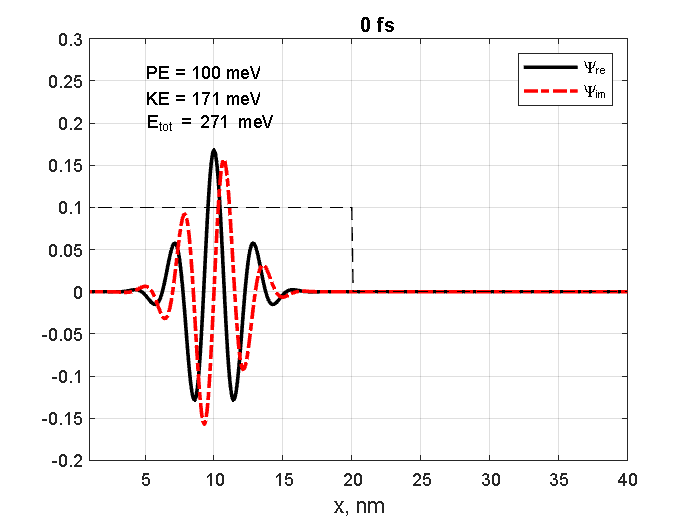


NN = 400;
hbar = 1.054e-34;
m0 = 9.1e-31;
eV2J = 1.6e-19;     
J2eV = 1 / eV2J;

dx = 0.1e-9;
dt = 2e-17;
ra = (0.5 * hbar / m0) * (dt / dx^2);
x = (dx * 1e9 : dx * 1e9 : dx * 1e9 * NN);

V = zeros(1, NN);
V(1, 1:200) = 0.1 * eV2J;

lambda = 30;
sigma = 20;
nc = 100;

psi = exp(-((x * 10 - nc) .^2 / (2 * sigma ^ 2)) + 1i * (2 * pi / lambda) .* (x * 10 - nc));
psi_norm = sqrt(sum(psi .* conj(psi)));

prl = real(psi) ./ psi_norm;
pim = imag(psi) ./ psi_norm;

n_step = 0;
n = 2 : NN - 1;
for i = 1 : n_step
    prl(n) = prl(n) - ra * (pim(n - 1) -2 * pim(n) + pim(n + 1)) ...
            + (dt / hbar) .* V(n) .* pim(n);
    pim(n) = pim(n) + ra * (prl(n - 1) - 2 * prl(n) + prl(n + 1)) ...
            - (dt / hbar) .* V(n) .* prl(n);
end

PE = 0.;
for n = 1 : NN
    psi(n) = prl(n) + 1i * pim(n);
    PE = PE + psi(n) * psi(n)' * V(n) * J2eV;
end

ke = 0. + 1i * 0.;
for n = 2 : NN - 1
    tmp = psi(n + 1) - 2 * psi(n) + psi(n - 1);
    ke = ke + tmp * psi(n)';
end
KE = -J2eV * ((hbar / dx) ^2 / (2 * m0)) * real(ke);

plot(x, prl, 'k', 'LineWidth', 2);
hold on
plot(x, pim,'-.r', 'LineWidth', 2);
plot(x, J2eV * V, '--k');

axis([1 dx * 1e9 * NN -0.2 0.3 ]);
title(sprintf('%7.0f fs', n_step * 2 / 100));

text(5, 0.23, sprintf('KE = %i meV', round(KE * 1e3)));
text(5, 0.26, sprintf('PE = %i meV', round(PE * 1e3)));
text(5, 0.2, sprintf('E_{tot} = %i meV', round(KE * 1e3) + round(PE * 1e3)));
    
xlabel('x, nm', 'FontSize', 12);
legend('\Psi_{re}', '\Psi_{im}');

grid on;